datapath = ...
    {"/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0830AchsensorHCICI004/",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0910AchsensorHPC002/",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0910AchsensorHPC004/",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/1216AchsensorHPCICI004/",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/1216AchsensorHPCICI004/",...
    "/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/090921AchsensorHPC002"...
    }

datapath = 1×6 cell array
    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0830AchsensorHCICI004/"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0910AchsensorHPC002/"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/0910AchsensorHPC004/"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/1216AchsensorHPCICI004/"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/1216AchsensorHPCICI004/"]}    {["/Volumes/yaochen/Active/Pingchuan/2022Fall/AChsensor_slice/090921AchsensorHPC002"]}




StateYao_file = ...
    {"analysis_offset0_ROIadjusted_20221214.mat",...
    "analysis_offset0_ROI_adjusted_20221214.mat",...
    "analysis_offset0_ROIadjusted_20221214.mat",...
    "analysis_offset0/1216AchsensorHPCICI004_Analysis2022-09-24.mat",...
    "analysis_offset0_cycle3_ROI_adjustment/1216AchsensorHPCICI004_Analysis2022-11-07.mat",...
    "analysis_offset0_ROI_adjustment/090921AchsensorHPC002_Analysis2022-11-07.mat"...
    }

StateYao_file = 1×6 cell array
    {["analysis_offset0_ROIadjusted_20221214.mat"]}    {["analysis_offset0_ROI_adjusted_20221214.mat"]}    {["analysis_offset0_ROIadjusted_20221214.mat"]}    {["analysis_offset0/1216AchsensorHPCICI004_Analysis2022-09-24.mat"]}    {["analysis_offset0_cycle3_ROI_adjustment/1216AchsensorHPCICI004_Analysis2022-11-07.mat"]}    {["analysis_offset0_ROI_adjustment/090921AchsensorHPC002_Analysis2022-11-07.mat"]}



CyclePositions_all = ...
    {[1],...
    [1],...
    [1],...
    [1 2],...
    [3],...
    [1]...
    }

CyclePositions_all = 1×6 cell array
    {[1]}    {[1]}    {[1]}    {[1 2]}    {[3]}    {[1]}



summary_files = {};
summary_path = '/Volumes/yaochen/Active/Pingchuan/2023SPR/Slice_flow_in_summaries'

summary_path = '/Volumes/yaochen/Active/Pingchuan/2023SPR/Slice_flow_in_summaries'

all_epochs = [2 3 4 5 6 7]; % all the epochs
drug_epochs = [2 3 4 5 6 7];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)


baseline_acq_num = 10; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 10; % epoch based response calculation

for i = 1:6
    cd(datapath{i})
    load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

%     save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
    currTime = datestr(datetime('now'));
    currTime = currTime(1:11);
    copyfile([stateYao.baseName, '_', currTime, '.mat'], summary_path)
    summary_files{i} = [stateYao.baseName,'_',currTime, '_EC50.mat'];

end

cd(summary_path)
save()

CyclePositions =      1     2


Cycle position 2, cell 1 in image 140, mask is empty.
Cycle position 2, cell 1 in image 142, mask is empty.
Cycle position 2, cell 1 in image 147, mask is empty.
Cycle position 2, cell 1 in image 148, mask is empty.
Cycle position 2, cell 1 in image 149, mask is empty.
Cycle position 2, cell 1 in image 150, mask is empty.
Cycle position 2, cell 1 in image 151, mask is empty.
Cycle position 2, cell 1 in image 152, mask is empty.
Cycle position 2, cell 1 in image 153, mask is empty.
Cycle position 2, cell 1 in image 154, mask is empty.
Cycle position 2, cell 1 in image 155, mask is empty.
Cycle position 2, cell 1 in image 156, mask is empty.
Cycle position 2, cell 1 in image 157, mask is empty.
Cycle position 2, cell 1 in image 158, mask is empty.
Cycle position 2, cell 1 in image 159, mask is empty.
Cycle position 2, cell 1 in image 160, mask is empty.
Cycle position 2, cell 1 in image 161, mask is empty.
Cycle position 2, cell 1 in image 162, mask is empty.


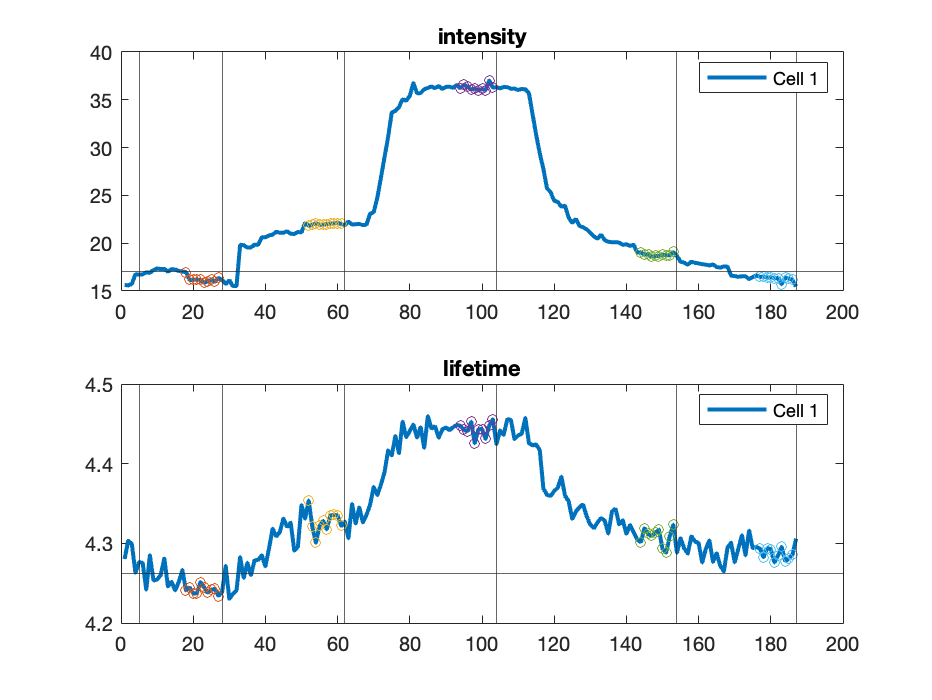

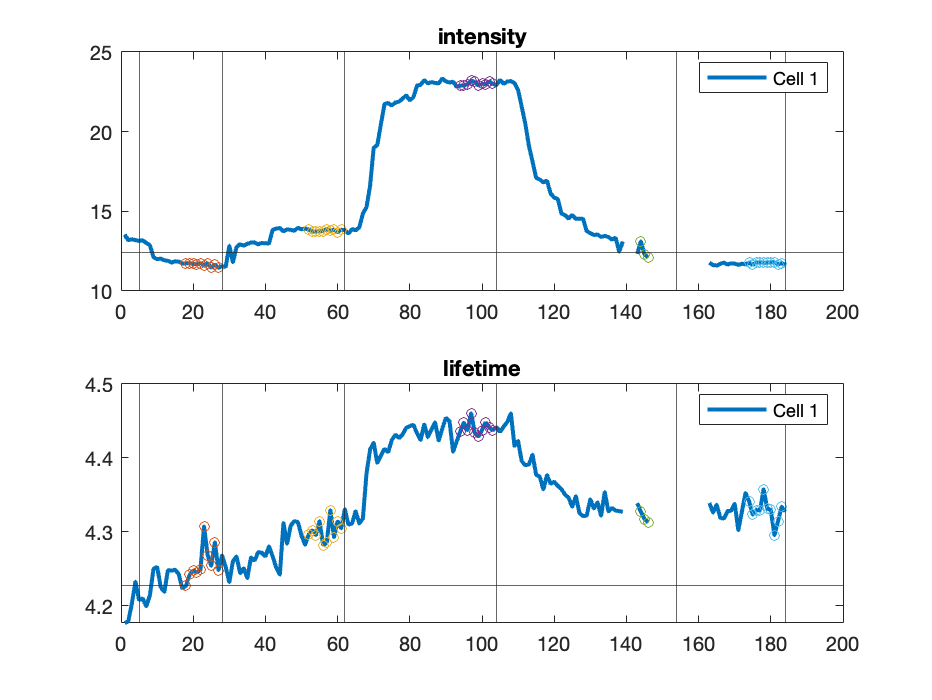

epoch_response_intensity_norm_all = 1×2 cell array
    {5×1 double}    {5×1 double}


epoch_response_lft_norm_all = 1×2 cell array
    {5×1 double}    {5×1 double}


epoch_response_intensity_all = 1×2 cell array
    {5×1 double}    {5×1 double}


epoch_response_lft_all = 1×2 cell array
    {5×1 double}    {5×1 double}


for i = 4
    cd(datapath{i})
    load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

CyclePositions = 3

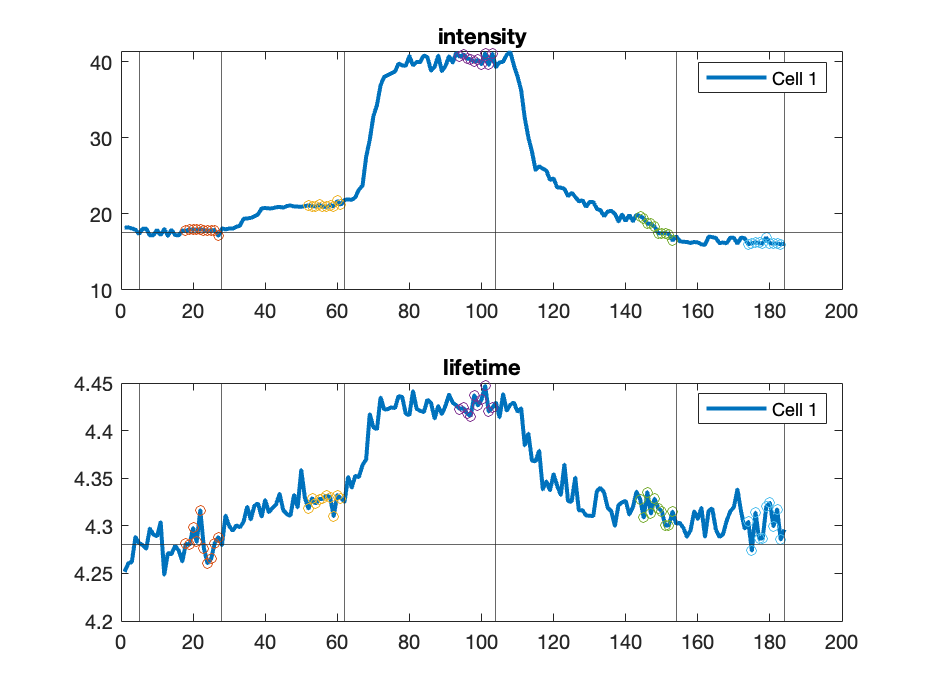

epoch_response_intensity_norm_all = 1×3 cell array
    {0×0 double}    {0×0 double}    {5×1 double}


epoch_response_lft_norm_all = 1×3 cell array
    {0×0 double}    {0×0 double}    {5×1 double}


epoch_response_intensity_all = 1×3 cell array
    {0×0 double}    {0×0 double}    {5×1 double}


epoch_response_lft_all = 1×3 cell array
    {0×0 double}    {0×0 double}    {5×1 double}


for i = 5
    cd(datapath{i})
    load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

CyclePositions = 1

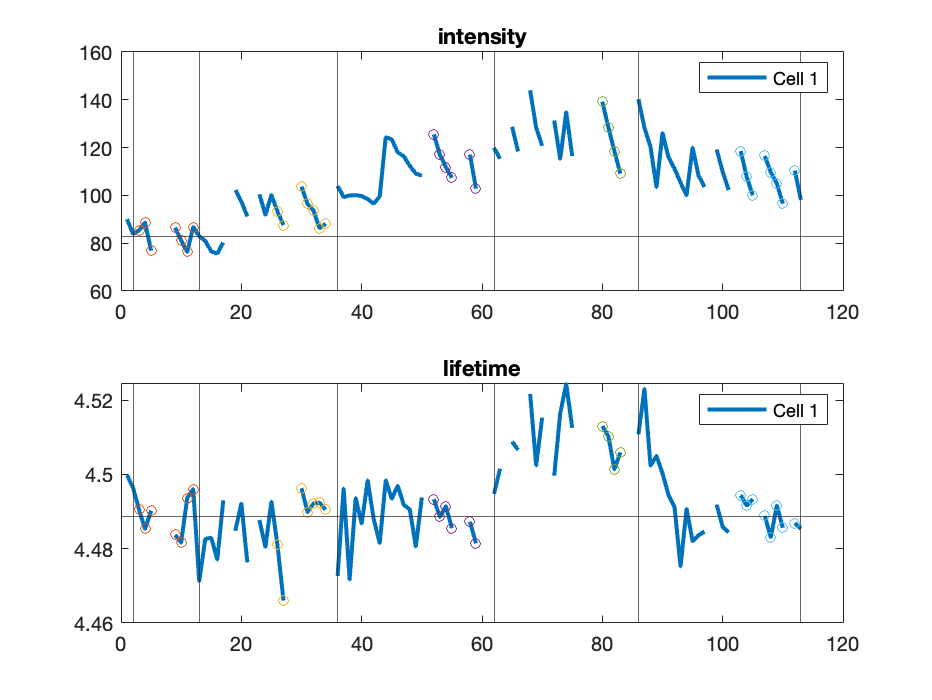

epoch_response_intensity_norm_all = 1×1 cell array
    {5×1 double}


epoch_response_lft_norm_all = 1×1 cell array
    {5×1 double}


epoch_response_intensity_all = 1×1 cell array
    {5×1 double}


epoch_response_lft_all = 1×1 cell array
    {5×1 double}


for i = 1
    cd(datapath{i})
%     load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

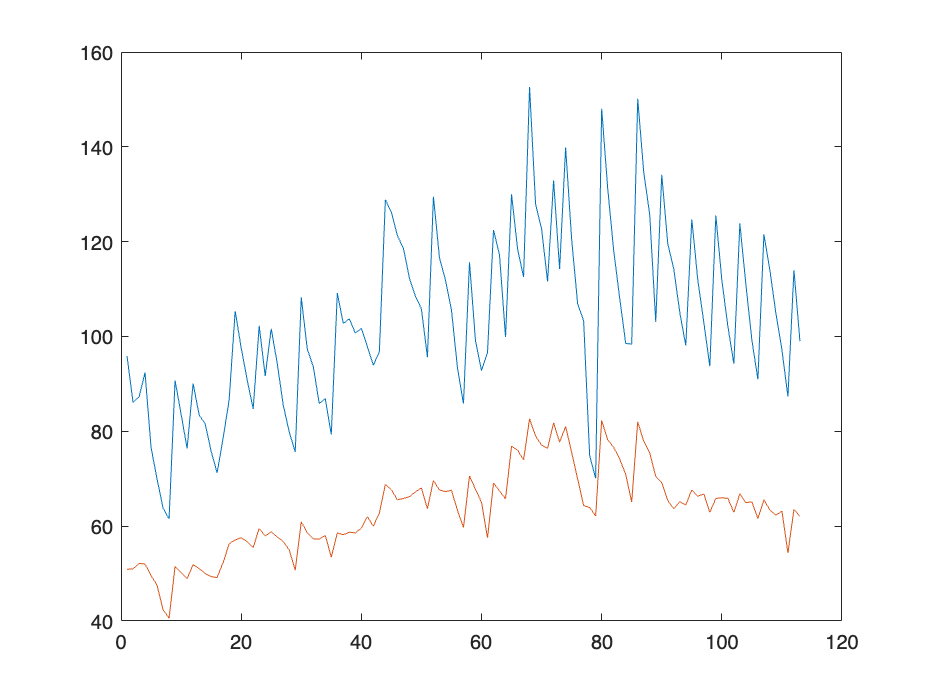

figure
plot(intensity_all{1}(:,1))
hold on
plot(intensity_all{1}(:,4))

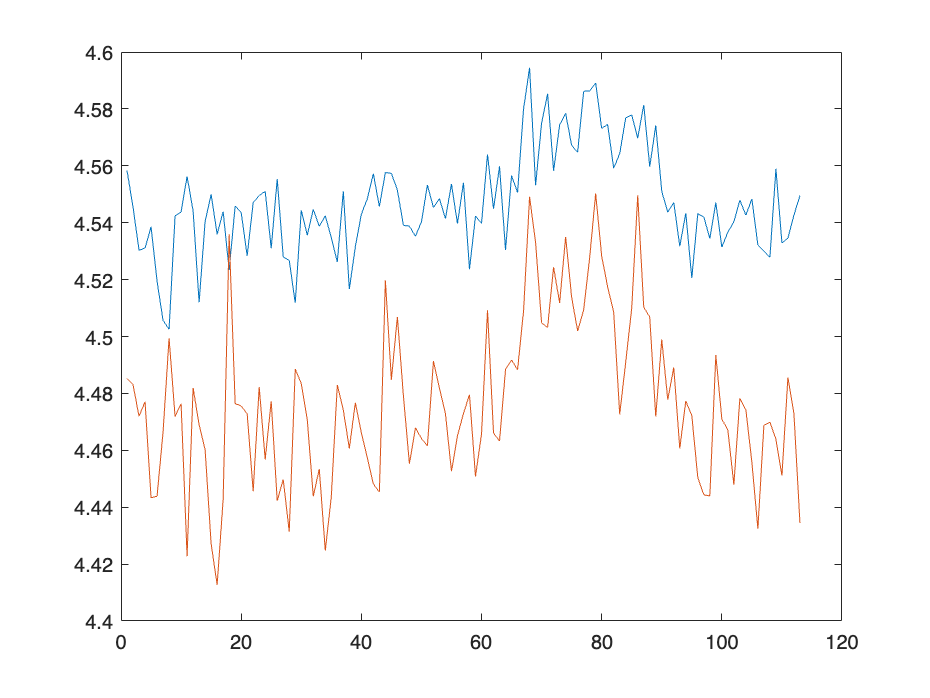

figure
plot(lft_all{1}(:,1))
hold on
plot(lft_all{1}(:,4))

CyclePositions = 1

Cycle position 1, cell 1 in image 219, mask is empty.
Cycle position 1, cell 1 in image 220, mask is empty.
Cycle position 1, cell 1 in image 221, mask is empty.


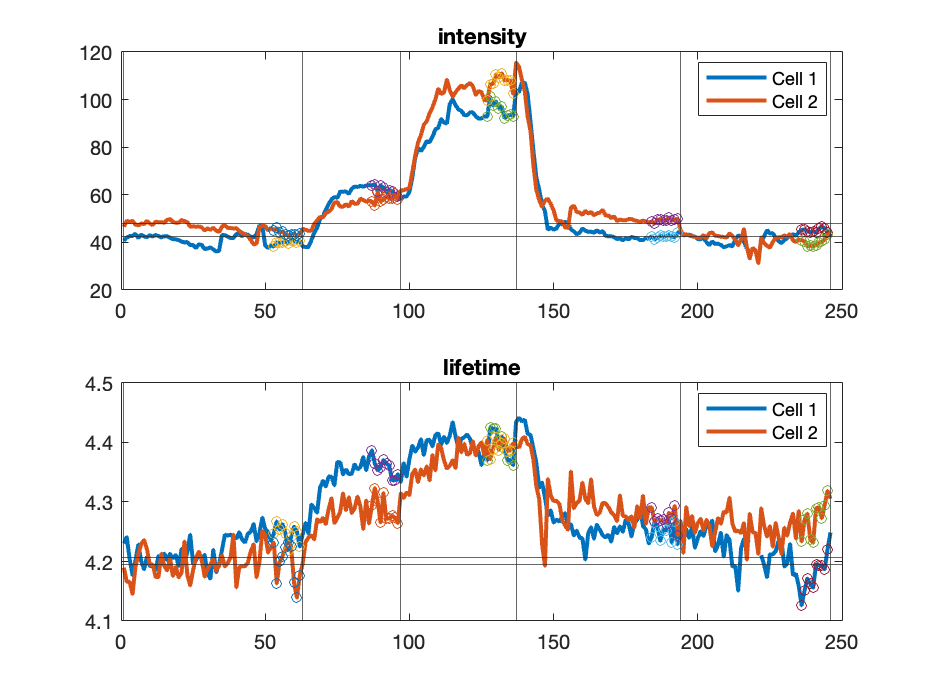

epoch_response_intensity_norm_all = 1×1 cell array
    {5×2 double}


epoch_response_lft_norm_all = 1×1 cell array
    {5×2 double}


epoch_response_intensity_all = 1×1 cell array
    {5×2 double}


epoch_response_lft_all = 1×1 cell array
    {5×2 double}


for i = 6
    cd(datapath{i})
    load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

CyclePositions = 1

Cycle position 1, cell 2 in image 241, mask is empty.
Cycle position 1, cell 2 in image 243, mask is empty.


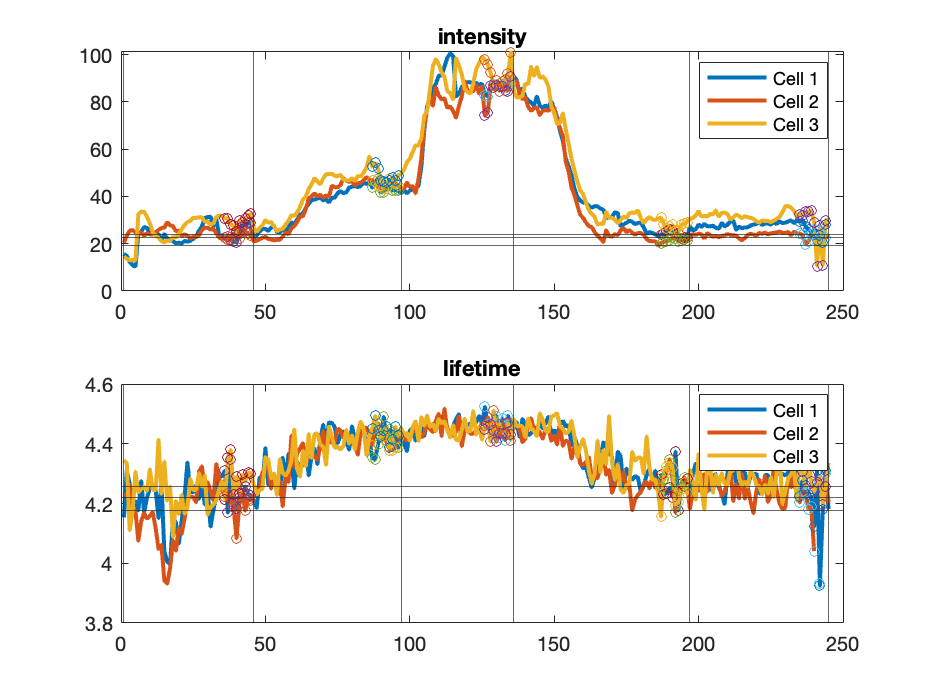

epoch_response_intensity_norm_all = 1×1 cell array
    {5×3 double}


epoch_response_lft_norm_all = 1×1 cell array
    {5×3 double}


epoch_response_intensity_all = 1×1 cell array
    {5×3 double}


epoch_response_lft_all = 1×1 cell array
    {5×3 double}


for i = 2
    cd(datapath{i})
%     load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

CyclePositions = 1

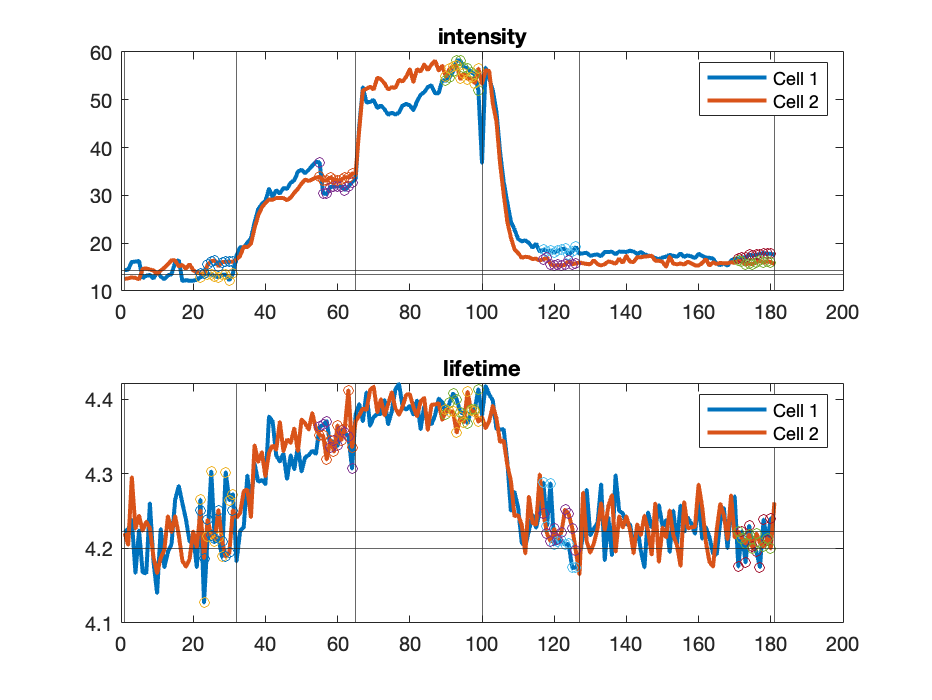

epoch_response_intensity_norm_all = 1×1 cell array
    {5×2 double}


epoch_response_lft_norm_all = 1×1 cell array
    {5×2 double}


epoch_response_intensity_all = 1×1 cell array
    {5×2 double}


epoch_response_lft_all = 1×1 cell array
    {5×2 double}


for i = 3
    cd(datapath{i})
%     load(StateYao_file{i})
    CyclePositions = CyclePositions_all{i}

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

datapath = ...
    {"/Volumes/yaochen/Active/Pingchuan/2020FL/1207AchsensorHPCICI003",...
"/Volumes/yaochen/Active/Pingchuan/2020FL/1026AchsensorHippocampus004",...
"/Volumes/yaochen/Active/Pingchuan/2021Fall/090821AchsensorHPC002",...
    }

datapath = 1×3 cell array
    {["/Volumes/yaochen/Active/Pingchuan/2020FL/1207AchsensorHPCICI003"]}    {["/Volumes/yaochen/Active/Pingchuan/2020FL/1026AchsensorHippocampus004"]}    {["/Volumes/yaochen/Active/Pingchuan/2021Fall/090821AchsensorHPC002"]}




StateYao_file = ...
    {"analysis_offset0_20221214.mat",...
    "analysis_offset0_ROIadjusted_20221215.mat",...
    "analysis_offset0_20221215.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_offset0_20221214.mat"]}    {["analysis_offset0_ROIadjusted_20221215.mat"]}    {["analysis_offset0_20221215.mat"]}



CyclePositions_all = ...
    {[1],...
    [1 2 3],...
    [1]...
    }

CyclePositions_all = 1×3 cell array
    {[1]}    {[1 2 3]}    {[1]}


all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)


baseline_acq_num = 10; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 10; % epoch based response calculation

i = 1

i = 1

cd(datapath{i})
load(StateYao_file{i})
CyclePositions = CyclePositions_all{i}

CyclePositions = 1

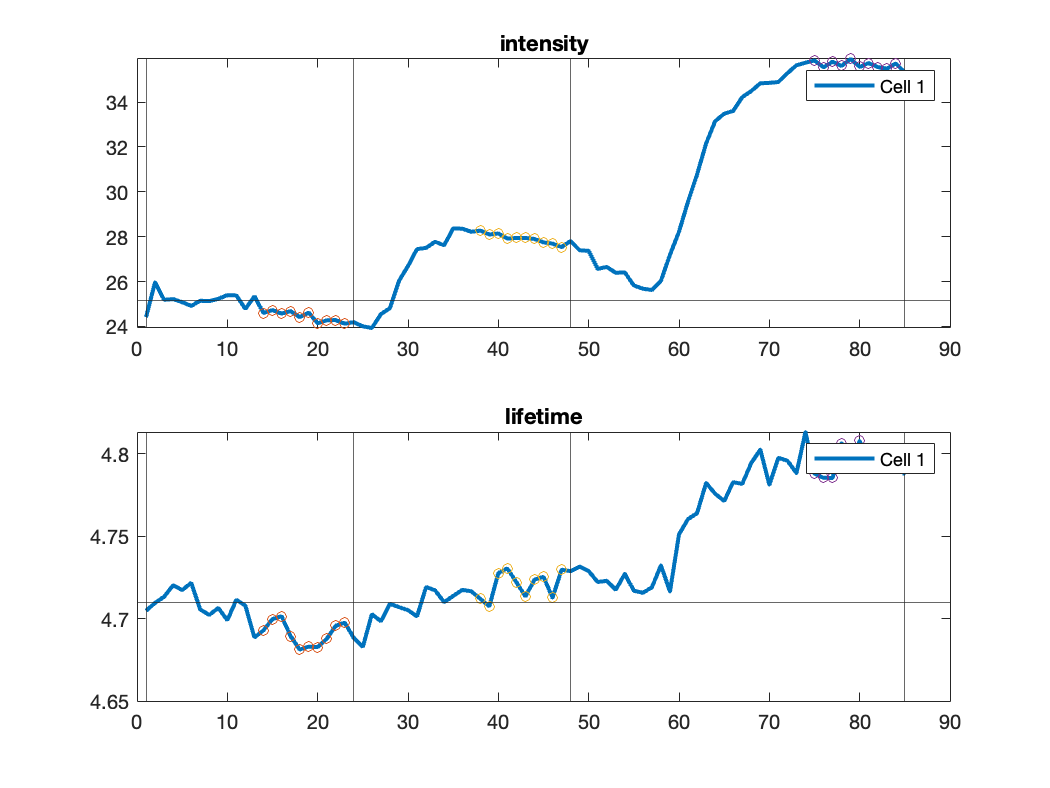

epoch_response_intensity_norm_all = 1×1 cell array
    {3×1 double}


epoch_response_lft_norm_all = 1×1 cell array
    {3×1 double}


epoch_response_intensity_all = 1×1 cell array
    {3×1 double}


epoch_response_lft_all = 1×1 cell array
    {3×1 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)


save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')

i = 2

i = 2

cd(datapath{i})
load(StateYao_file{i})
CyclePositions = CyclePositions_all{i}

CyclePositions =      1     2     3


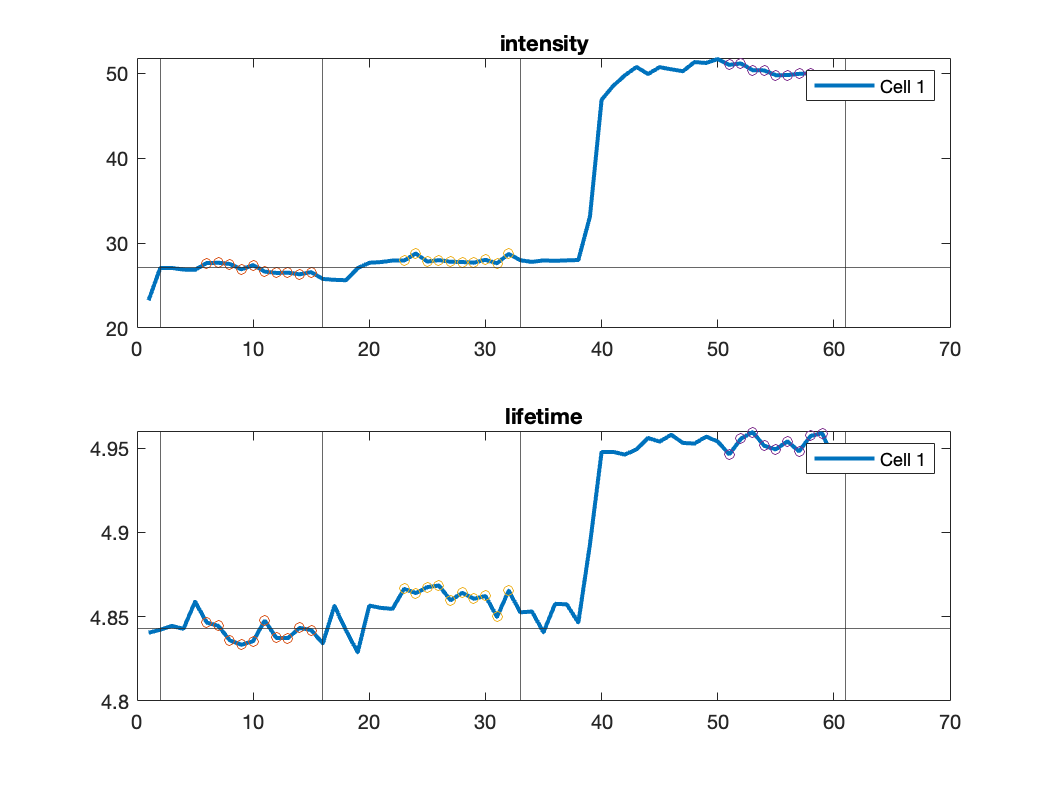

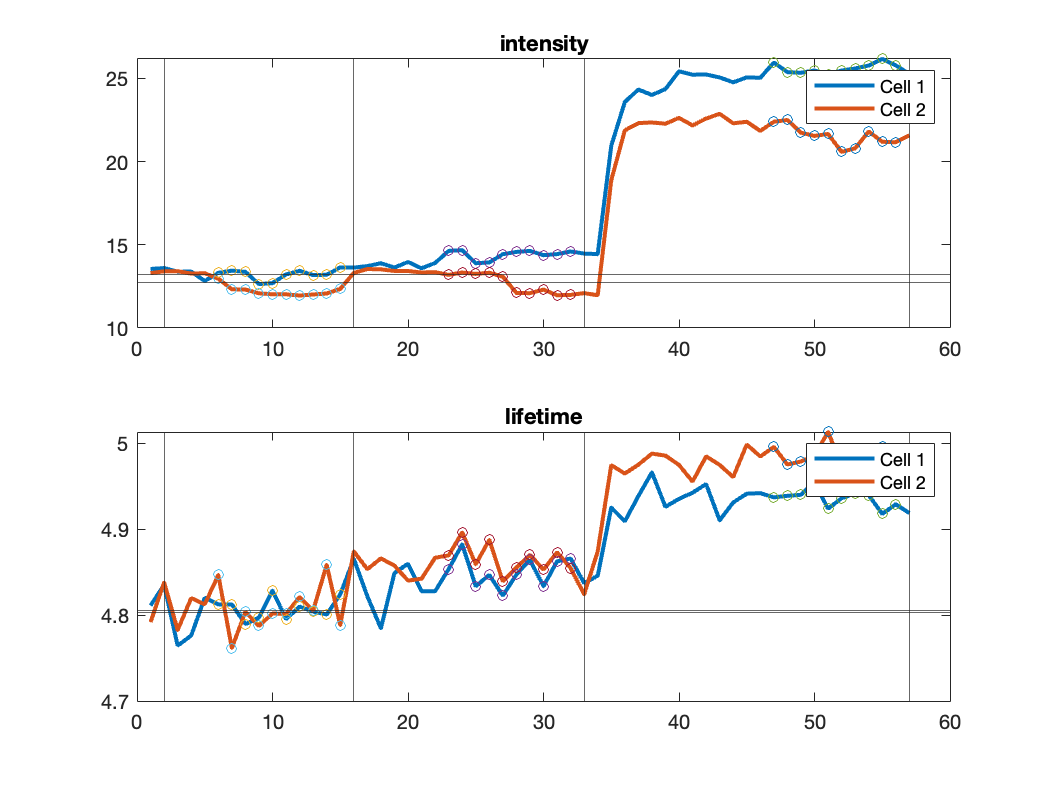

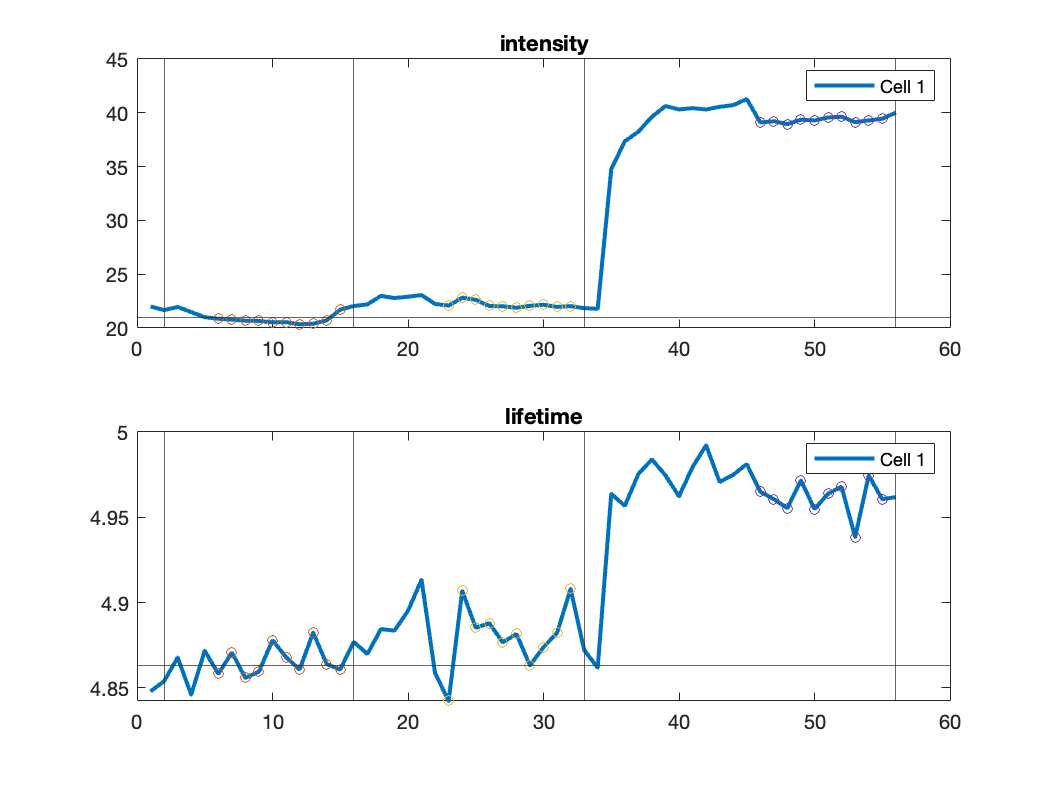

epoch_response_intensity_norm_all = 1×3 cell array
    {3×1 double}    {3×2 double}    {3×1 double}


epoch_response_lft_norm_all = 1×3 cell array
    {3×1 double}    {3×2 double}    {3×1 double}


epoch_response_intensity_all = 1×3 cell array
    {3×1 double}    {3×2 double}    {3×1 double}


epoch_response_lft_all = 1×3 cell array
    {3×1 double}    {3×2 double}    {3×1 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)


save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')

i = 3

i = 3

cd(datapath{i})
load(StateYao_file{i})
CyclePositions = CyclePositions_all{i}

CyclePositions = 1

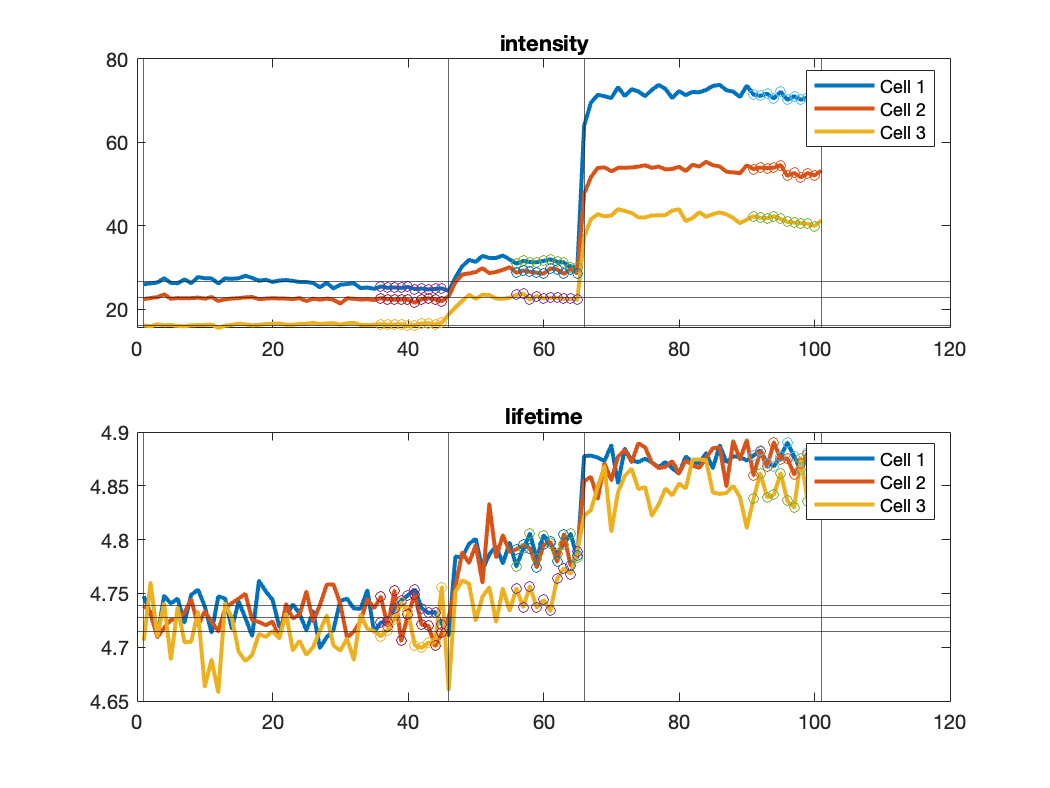

epoch_response_intensity_norm_all = 1×1 cell array
    {3×3 double}


epoch_response_lft_norm_all = 1×1 cell array
    {3×3 double}


epoch_response_intensity_all = 1×1 cell array
    {3×3 double}


epoch_response_lft_all = 1×1 cell array
    {3×3 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)


save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')